# Website Crawling for SEO Analytics

Use this script to systematically visit all links in a website, its pages, and subpages, and analyze the keywords used in them.

## Use a WebCrawler to explore your website

Define your website as the inital URL to explore. Define the maximum number of links to explore. 

website = "https://www.wikipedia.org/wiki/Stoicism";
maxLinks = 200;

Include only URLs that are part of this website

filter = @(url) contains(url, "wikipedia");

Create the WebCrawler object and configure it:

crawler = WebCrawler();
crawler.maxLinks = maxLinks;
crawler.filter = filter;

Run a website exploration:

tic
crawler.explore(website);
timeToExplore = toc

timeToExplore = 148.2815

List the visited pages:

array2table(crawler.VisitedURLs, "VariableNames", "Explored Sites")

ans = 244×1 table
                                Explored Sites                            
    ______________________________________________________________________

    "https://www.wikipedia.org/wiki/Stoicism"                             
    "https://af.wikipedia.org/wiki/Sto%C3%AFsisme"                        
    "https://af.m.wikipedia.org/w/index.php"                              
    "https://af.m.wikipedia.org/wiki/13de_eeu"                            
    "https://af.m.wikipedia.org/wiki/1201"                                
    "https://ab.wikipedia.org/wiki/1201"                                  
    "https://ab.m.wikipedia.org/w/index.php"                              
    "https://aa.wikipedia.org/wiki/Main_Page"                             
    "https://aa.m.wikipedia.org/w/index.php"                              
    "https://aa.m.wikipedia.org/wiki/Main_Page"                           
    "https://aa.m.wikipedia.org/wiki/Special:Hi

Plot the exploration experience as a directed graph:

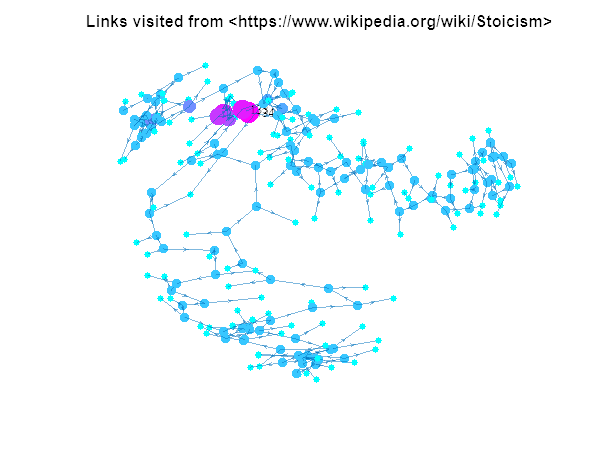

crawler.plotGraph();

Analyze the extracted keywords for each site:

crawler.Graph.Nodes.Keywords

ans = 244×1 cell array
    {10×1 string}
    {10×1 string}
    {10×1 string}
    {10×1 string}
    {10×1 string}
    {10×1 string}
    {10×1 string}
    { 0×1 string}
    { 6×1 string}
    { 6×1 string}
    {10×1 string}
    {10×1 string}
    {10×1 string}
    {10×1 string}
    {10×1 string}
    { 6×1 string}
